# 1

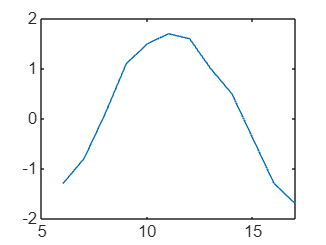

clear;clc

%(a)
Hour = [6;7;8;9;10;11;12;13;14;15;16;17];
SolarGen = [0.5;1.2;2.4;3.8;4.6;5.1;5.4;5.0;4.2;3.0;1.7;0.8];
Demand = [1.8;2.0;2.3;2.7;3.1;3.4;3.8;4.0;3.7;3.4;3.0;2.5];
Battery = [3.2;3.0;3.1;3.8;4.5;5.2;5.9;6.3;6.5;6.1;5.4;4.7];

%(b)
A = [Hour, SolarGen, Demand, Battery];

%(c)
writematrix(A, 'solar_system.txt','Delimiter', 'space');

%(d)
B = zeros(size(A));
B = load('solar_system.txt');

%(e)
hour = B(:,1);
solar = B(:,2);
demand = B(:,3);
battery = B(:,4);

%(f)
netPower = solar - demand;

%(g)
plot(hour,netPower);

# 2

clear;clc

%(a)
D = [ 1 2.1 8 12; 2 3.4 13 19; 3 1.8 7 10; 4 5.2 21 31; 5 4.7 19 28; 6 6.0 25 36; 7 3.1 12 18; 8 5.8 24 35];

%(b)
writematrix(D,'drone_delivery.txt');
Drone = load('drone_delivery.txt');

%(c)
RouteID = Drone(:,1);
DistanceKm = Drone(:,2);
TimeMin = Drone(:,3);
BatteryUsed = Drone(:,4);

%(d)
speed = DistanceKm ./ TimeMin;

%(e)
BatteryPerKm = BatteryUsed ./ DistanceKm;

%(f)
idex = BatteryPerKm > 6;
FinalRoute = [RouteID(idex), DistanceKm(idex), BatteryPerKm(idex)];
disp(FinalRoute)

    8.0000    5.8000    6.0345



# 3

clear;clc

%(a)
Zone = ["Z1"; "Z2"; "Z3"; "Z4"; "Z5"; "Z6"; "Z7"; "Z8"];
Temp = [22.5; 24.1; 21.8; 25.3; 23.7; 26.0; 22.9; 24.8];
Humidity = [61; 58; 67; 55; 62; 53; 65; 57];
Light = [420; 460; 390; 520; 480; 550; 410; 500];
CO2 = [510; 540; 495; 610; 575; 640; 520; 600];

%(b)
Farm = table(Zone, Temp, Humidity, Light, CO2);

%(c)
Farm.EnvIndex = 0.4*Farm.Temp + 0.01*Farm.Light + 0.02*Farm.CO2;

%(d)
index = Farm.EnvIndex >= 25;
HighEnv = Farm(index,:);

%(e)
HighEnv(:, {'Zone', 'Temp', 'Light', 'EnvIndex'})

ans = 5×4 table
    Zone    Temp    Light    EnvIndex
    ____    ____    _____    ________

    "Z2"    24.1     460      25.04  
    "Z4"    25.3     520      27.52  
    "Z5"    23.7     480      25.78  
    "Z6"      26     550       28.7  
    "Z8"    24.8     500      26.92  


# 4

clear;clc

%(a)
Machine = ["M1" "M2" "M3" "M4" "M5" "M6" "M7" "M8" "M9" "M10"]';
Vibration = [1.8 2.4 1.5 3.1 2.7 1.9 3.5 2.2 1.6 2.9]';
Temp = [68 72 65 78 74 69 82 71 66 76]';
Power = [4.5 5.1 4.2 6.3 5.7 4.8 6.8 5.0 4.4 6.0]';
Defect = [2 5 1 8 6 3 10 4 1 7]';
Factory = table(Machine, Vibration, Temp, Power, Defect);

%(b)
Factory.RiskScore = Vibration .*Temp./Power;

%(c)
index = Factory.RiskScore >= 35 & Defect >= 6;
RiskMachines = Factory(index,:);

%(d)
RiskMachines(:, {'Machine', 'RiskScore', 'Defect'})

ans = 4×3 table
    Machine    RiskScore    Defect
    _______    _________    ______

     "M4"       38.381         8  
     "M5"       35.053         6  
     "M7"       42.206        10  
     "M10"      36.733         7  



%(e)
writetable(Factory,"Factory_risk.csv");

# 5

clear;clc

%(a)
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data';

%(b)
Abalone = readtable(url, 'FileType', 'text', 'ReadVariableNames',false);

%(c)
Abalone.Properties.VariableNames = {'Sex','Length','Diameter','Height','WholeWeight','ShuckedWeight','VisceraWeight', 'ShellWeight','Rings'};

%(d)
Abalone(:, {'WholeWeight','ShellWeight','Rings'})

ans = 4177×3 table
    WholeWeight    ShellWeight    Rings
    ___________    ___________    _____

       0.514           0.15        15  
      0.2255           0.07         7  
       0.677           0.21         9  
       0.516          0.155        10  
       0.205          0.055         7  
      0.3515           0.12         8  
      0.7775           0.33        20  
       0.768           0.26        16  
      0.5095          0.165         9  
      0.8945           0.32        19  
      0.6065           0.21        14  
       0.406          0.135        10  
      0.5415           0.19        11  
      0.6845          0.205        10  
      0.4755          0.185        10  
      0.6645           0.24        12  



%(e)
index = strcmp(Abalone.Sex,'M') & Abalone.Rings >= 15;
OldMale = Abalone(index,:);

%(f)
OldMale(:,{'Sex','Length','WholeWeight','Rings'})

ans = 167×4 table
     Sex     Length    WholeWeight    Rings
    _____    ______    ___________    _____

    {'M'}    0.455        0.514        15  
    {'M'}    0.605       0.9365        15  
    {'M'}    0.665        1.338        18  
    {'M'}    0.595       1.3175        21  
    {'M'}    0.565       0.8115        15  
    {'M'}    0.695        1.494        15  
    {'M'}     0.55        0.843        15  
    {'M'}     0.53        0.883        15  
    {'M'}      0.7       1.7255        19  
    {'M'}     0.71        1.959        18  
    {'M'}    0.595        1.262        17  
    {'M'}     0.65       1.3445        16  
    {'M'}     0.59        1.053        15  
    {'M'}    0.645        1.514        16  
    {'M'}     0.64        1.368        21  
    {'M'}     0.64       1.3035        16  


# 6

%(a)
Abalone;

%(b)
Abalone.ShellRatio = Abalone.ShellWeight ./ Abalone.WholeWeight;

%(c)
index2 = Abalone.ShellRatio >= 0.25 & Abalone.Rings >= 12;
HardShell = Abalone(index2,:);

%(d)
HardShell(:,{'Sex','WholeWeight','ShellWeight','ShellRatio','Rings'})

ans = 896×5 table
     Sex     WholeWeight    ShellWeight    ShellRatio    Rings
    _____    ___________    ___________    __________    _____

    {'M'}       0.514           0.15        0.29183       15  
    {'F'}      0.7775           0.33        0.42444       20  
    {'F'}       0.768           0.26        0.33854       16  
    {'F'}      0.8945           0.32        0.35774       19  
    {'F'}      0.6065           0.21        0.34625       14  
    {'M'}      0.6645           0.24        0.36117       12  
    {'F'}      0.9395           0.27        0.28739       12  
    {'M'}       0.931           0.28        0.30075       12  
    {'M'}      0.9365          0.295          0.315       15  
    {'F'}       1.639           0.46        0.28066       15  
    {'M'}       1.338           0.35        0.26158       18  
    {'F'}       1.798          0.455        0.25306       19  
    {'F'}      1.7095           0.49        0.28663       13  
    {'F'}       1.217           0.34


%(e)
ratioData = HardShell{:, 'ShellRatio'};

# 7

clear; clc

%(a)
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv';

%(b)
ForestFires = readtable(url);

%(c)
temp = ForestFires.temp;
RH = ForestFires.RH;
wind = ForestFires.wind;
rain = ForestFires.rain;
area = ForestFires.area;

%(d)
index = temp >= 25 & RH <= 35;
HotDryFires = ForestFires(index, :);

%(e)
HotDryFires(:, {'month', 'day', 'temp', 'RH', 'wind', 'area'})

ans = 54×6 table
     month       day      temp    RH    wind     area 
    _______    _______    ____    __    ____    ______

    {'sep'}    {'wed'}    26.4    21    4.5          0
    {'sep'}    {'sat'}    30.2    24    2.7          0
    {'sep'}    {'fri'}    25.4    24    3.6          0
    {'sep'}    {'wed'}    25.9    24      4          0
    {'sep'}    {'thu'}    27.7    24    2.2          0
    {'sep'}    {'fri'}    27.6    30    1.3          0
    {'sep'}    {'thu'}    25.4    27    2.2          0
    {'aug'}    {'thu'}    27.4    22      4        0.9
    {'sep'}    {'sat'}    29.6    27    2.7       1.46
    {'sep'}    {'sat'}    28.6    27    2.2       1.61
    {'sep'}    {'sun'}    28.3    26    3.1       64.1
    {'sep'}    {'wed'}    26.4    21    4.5      88.49
    {'sep'}    {'sun'}    27.8    27    3.1      95.18
    {'sep'}    {'sat'}    25.1    27      4     1090.8
    {'aug'}    {'wed'}    28.7    28    2.7          0
    {'aug'}    {'wed'}    26.8    25    3.1    

# 8

%(a)
Fire = ForestFires;

%(b)
Fire.RiskIndex = Fire.temp .* Fire.wind ./ Fire.RH;

%(c)
index = Fire.RiskIndex >= 2 & Fire.area > 0;
RiskFire = Fire(index, :);

%(d)
RiskFire(:, {'month', 'day', 'temp', 'RH', 'wind', 'area', 'RiskIndex'})

ans = 105×7 table
     month       day      temp    RH    wind    area    RiskIndex
    _______    _______    ____    __    ____    ____    _________

    {'aug'}    {'wed'}    23.3    31    4.5     0.55     3.3823  
    {'aug'}    {'fri'}    21.2    51    8.9     0.61     3.6996  
    {'aug'}    {'wed'}    23.8    32    5.4     0.77     4.0163  
    {'aug'}    {'thu'}    27.4    22      4      0.9     4.9818  
    {'sep'}    {'tue'}    24.2    28    3.6     0.96     3.1114  
    {'aug'}    {'tue'}    17.4    43    6.7     1.07     2.7112  
    {'sep'}    {'thu'}    23.7    25    4.5     1.12      4.266  
    {'jun'}    {'fri'}    23.2    39    5.4     1.19     3.2123  
    {'sep'}    {'fri'}    20.1    47    4.9     1.46     2.0955  
    {'sep'}    {'sat'}    29.6    27    2.7     1.46       2.96  
    {'sep'}    {'sat'}    28.6    27    2.2     1.61     2.3304  
    {'aug'}    {'wed'}    20.5    35      4     1.64     2.3429  
    {'sep'}    {'fri'}      19    34    5.8     1.69     


%(e)
writetable(RiskFire, 'forest_risk.csv');

# 9

clear; clc

%(a)
P = readtable('penguins.csv');


%(b)
P.Properties.VariableNames

ans = 1×19 cell 배열
    {'studyName'}    {'SampleNumber'}    {'species'}    {'Region'}    {'Latitude'}    {'Longitude'}    {'island'}    {'Stage'}    {'IndividualID'}    {'ClutchCompletion'}    {'DateEgg'}    {'bill_length_mm'}    {'bill_depth_mm'}    {'flipper_length_mm'}    {'body_mass_g'}    {'sex'}    {'Delta15N_o_oo_'}    {'Delta13C_o_oo_'}    {'Comments'}



%(c)
index = P.body_mass_g >= 4500;
HeavyPenguins = P(index, :);

%(d)
HeavyPenguins(:, {'species', 'island', 'body_mass_g', 'sex'})

ans = 118×4 table
                       species                          island        body_mass_g       sex    
    _____________________________________________    _____________    ___________    __________

    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4675        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4500        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4650        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4600        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4700        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4725        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4775        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4600        {'MALE'  }
    {'Chinstrap pengu


%(e)
index2 = strcmp(P.species, 'Gentoo') & P.body_mass_g >= 5000;
LargeGentoo = P(index2, :);

# 10

%(a)
P;

%(b)
P.BillRatio = P.bill_length_mm ./ P.bill_depth_mm;

%(c)
index = P.BillRatio >= 2.8;
LongBill = P(index, :);

%(d)
LongBill(:, {'species', 'bill_length_mm', 'bill_depth_mm', 'BillRatio'})

ans = 131×4 table
                       species                       bill_length_mm    bill_depth_mm    BillRatio
    _____________________________________________    ______________    _____________    _________

    {'Chinstrap penguin (Pygoscelis antarctica)'}         51.3             18.2          2.8187  
    {'Chinstrap penguin (Pygoscelis antarctica)'}           52             18.1          2.8729  
    {'Chinstrap penguin (Pygoscelis antarctica)'}           58             17.8          3.2584  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         47.5             16.8          2.8274  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         46.9             16.6          2.8253  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         50.9             17.9          2.8436  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         49.8             17.3          2.8786  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         48.1             16.4          2.9329  
 


%(e)
billRatioData = LongBill{:, 'BillRatio'};

# 11

clear; clc

%(a)
H = readtable('heart_failure.csv');

%(b)
H.Properties.VariableNames

ans = 1×13 cell 배열
    {'age'}    {'anaemia'}    {'creatinine_phosphokinase'}    {'diabetes'}    {'ejection_fraction'}    {'high_blood_pressure'}    {'platelets'}    {'serum_creatinine'}    {'serum_sodium'}    {'sex'}    {'smoking'}    {'time'}    {'DEATH_EVENT'}



%(c)
index = H.age >= 70 & H.ejection_fraction <= 35;
HighRisk = H(index, :);

%(d)
HighRisk(:, {'age', 'ejection_fraction', 'serum_creatinine', ...
    'serum_sodium', 'DEATH_EVENT'})

ans = 31×5 table
    age    ejection_fraction    serum_creatinine    serum_sodium    DEATH_EVENT
    ___    _________________    ________________    ____________    ___________

    75            20                   1.9              130              1     
    75            15                   1.2              137              1     
    80            35                   9.4              133              1     
    70            25                     1              140              1     
    75            30                  1.83              134              1     
    82            30                   1.2              132              1     
    70            20                  1.83              134              1     
    80            20                   4.4              133              1     
    95            30                     2              132              1     
    70            35                   2.7              138              0     
    72            20  


%(e)
DeathGroup = H(H.DEATH_EVENT == 1, :);
SurvivalGroup = H(H.DEATH_EVENT == 0, :);

# 12

%(a)
H ;

%(b)
H.RiskScore = H.age ./ H.ejection_fraction + H.serum_creatinine;

%(c)
index = H.RiskScore >= 4;
RiskScoreGroup = H(index, :);

%(d)
RiskScoreGroup(:, {'age', 'ejection_fraction', 'serum_creatinine', ...
    'RiskScore', 'DEATH_EVENT'})

ans = 59×5 table
    age    ejection_fraction    serum_creatinine    RiskScore    DEATH_EVENT
    ___    _________________    ________________    _________    ___________

    75            20                   1.9             5.65           1     
    65            20                   1.3             4.55           1     
    50            20                   1.9              4.4           1     
    65            20                   2.7             5.95           1     
    90            40                   2.1             4.35           1     
    75            15                   1.2              6.2           1     
    80            35                   9.4           11.686           1     
    75            38                     4           5.9737           1     
    45            14                   0.8           4.0143           1     
    75            30                  1.83             4.33           1     
    80            38                   1.9           4.005


%(e)
writetable(RiskScoreGroup, 'heart_risk_group.csv');

# 13

clear; clc

%(a)
B = readtable('bank-full.csv');

% 만약 열이 제대로 나뉘지 않으면 아래 코드 사용
% B = readtable('bank-full.csv', 'Delimiter', ';');

%(b)
B.Properties.VariableNames

ans = 1×17 cell 배열
    {'age'}    {'job'}    {'marital'}    {'education'}    {'default'}    {'balance'}    {'housing'}    {'loan'}    {'contact'}    {'day'}    {'month'}    {'duration'}    {'campaign'}    {'pdays'}    {'previous'}    {'poutcome'}    {'y'}



%(c)
age = B.age;
balance = B.balance;
loan = B.loan;
y = B.y;

%(d)
index = age >= 40 & balance >= 2000 & string(loan) == "no";
T1 = B(index, :);

%(e)
T2 = T1(:, {'age', 'balance', 'y'});

%(f)
T2.NewFlag = double(string(T2.y) == "yes");

%(g)
Subscribed = T2(T2.NewFlag == 1, :);

%(h)
balanceVec = Subscribed{:, 'balance'};

%(i)
avgBalance = mean(balanceVec);

%(j)
writetable(Subscribed, 'bank_selected.csv');